Homework #01

## 1

[1 png]


I_s=[1.78504; 0.398297; 0.624653; 0.462755];
mu=1.5;
I_0=8;

% log(x) is ln(x) in matlab
rhs = (-1./mu) .* log(I_s./I_0);

a=[0 0 0 1];
b=[0 1 1 0];
c=[0 1 0 1];
d=[1 1 0 0];

A = [a; b; c; d];
b=rhs;
rho = inv(A)*b

rho =     1.2000
    0.7000
    1.3000
    1.0000


% the 3rd pixel density is indeed 1.3 :)

## 2

A=[-4, -7, -12.4;...
8, -7, -17.2;...
2, -1, -2.8];
b=[1;-1;0];


2A) Row interpretation: each row is an equation (for a plane)

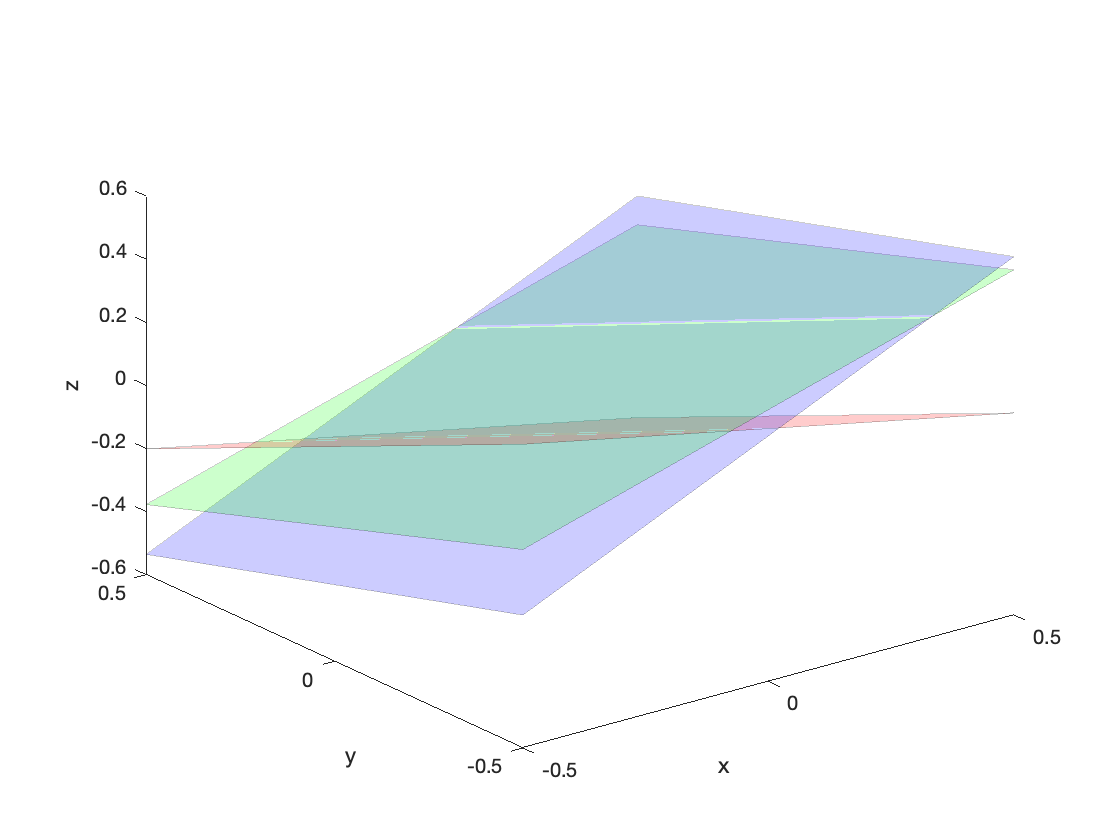

x=[-0.5,-0.5,0.5,0.5];
y=[0.5,-0.5,-0.5,0.5];
z1 = (b(1,1) - A(1,1).*x - A(1,2).*y)./A(1,3);
z2 = (b(2,1) - A(2,1).*x - A(2,2).*y)./A(2,3);
z3 = (b(3,1) - A(3,1).*x - A(3,2).*y)./A(3,3);

figure
hold on
% plot first plane:
p1=patch(x(:),y(:),z1(:),'red');
set(p1,'facealpha',0.2); set(p1,'edgealpha',0.2)
view(3);
xlabel('x')
ylabel('y')
zlabel('z')

% plot second plane:
p2=patch(x(:),y(:),z2(:),'green');
set(p2,'facealpha',0.2); set(p2,'edgealpha',0.2)

% plot third plane:
p3=patch(x(:),y(:),z3(:),'blue');
set(p3,'facealpha',0.2); set(p3,'edgealpha',0.2)

hold off

as plotted, there's no point where all three planes intersect at once

2B) Column interpretation: combination of columns as vectors

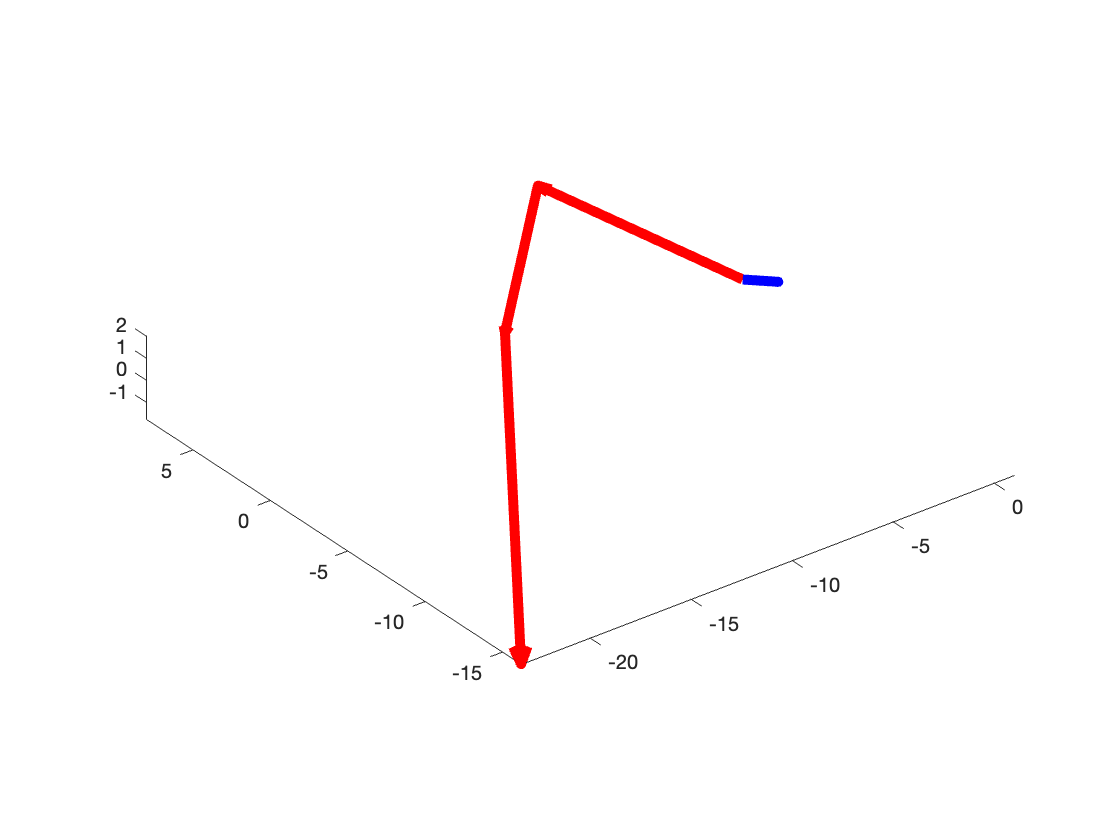

figure
ax = axes();
xlim(ax, [-20 20]);
ylim(ax, [-20 20]);
zlim(ax, [-20 20]);
view(ax, 3)
hold(ax, 'on')
quiver3(0,0,0, A(1,1),A(2,1),A(3,1), 1, 'Color', 'r','linewidth',5)
quiver3(A(1,1),A(2,1),A(3,1), A(1,2),A(2,2),A(3,2), 1, 'Color', 'r','linewidth',5)
quiver3(A(1,1)+A(1,2),A(2,1)+A(2,2),A(3,1)+A(3,2), A(1,3),A(2,3),A(3,3), 1, 'Color', 'r', 'linewidth',5)
quiver3(0,0,0, b(1,1),b(2,1),b(3,1), 1, 'Color', 'b','linewidth',5)
axis equal
hold off

as plotted, no span combination of the A col vectors (in red) would give the b vector (in blue)

## 3

A=[ -2, -1.33333, 0.666667;...
3, -1, 0;...
6, -5, 4];
b=[3;9;6];

[3a png]

3b)

[L,U,P]=lu(A)

L =     1.0000         0         0
   -0.3333    1.0000         0
    0.5000   -0.5000    1.0000


U =     6.0000   -5.0000    4.0000
         0   -3.0000    2.0000
         0         0   -1.0000


P =      0     0     1
     1     0     0
     0     1     0


disp(L*U)

    6.0000   -5.0000    4.0000
   -2.0000   -1.3333    0.6667
    3.0000   -1.0000         0



disp(P*A)

    6.0000   -5.0000    4.0000
   -2.0000   -1.3333    0.6667
    3.0000   -1.0000         0



[3c png]

3c continued)

x=A\b

x =     0.5555
   -7.3334
   -8.5000


## 4

[4a png]

% 4a continued
A=[ -9, -5, 1;...
5, -9, -2;...
1, -1, 10];
b=[1;-1;-1];

x_k1=[-0.1396; 0.0444; -0.0816]

x_k1 =    -0.1396
    0.0444
   -0.0816


% second set by code

x_ktemp=x_k1;
for i = 1:1:length(b)
    x_ktemp=x_ktemp+( 1.*norm(A(i,:)).^-2.*(( b(i,1)-(A(i,:)*x_ktemp) ).*A(i,:)'));
end
x_k2=x_ktemp

x_k2 =    -0.1466
    0.0476
   -0.0806


4b)

disp(['Error after 1 set: ' num2str(norm(x_k1 - (inv(A)*b)))])

Error after 1 set: 0.0076993


disp(['Error after 2 sets: ' num2str(norm(x_k2 - (inv(A)*b)))])

Error after 2 sets: 8.6556e-05


4c)

v_1 = A(1,:);
v_2 = A(2,:);
v_3 = A(3,:);
theta1 = rad2deg(atan2(norm(cross(v_1, v_2)), dot(v_1, v_2)))

theta1 = 91.0563

theta2 = rad2deg(atan2(norm(cross(v_1, v_3)), dot(v_1, v_3)))

theta2 = 86.7075

theta3 = rad2deg(atan2(norm(cross(v_2, v_3)), dot(v_2, v_3)))

theta3 = 93.2472

So because all my angles are pretty close to 90 degrees and are therefore close to perpendicular to each other, the Kaczmarz method (which makes lines perpendicular to the planes) will pretty quickly converge to close to the actual intersection.

4d)

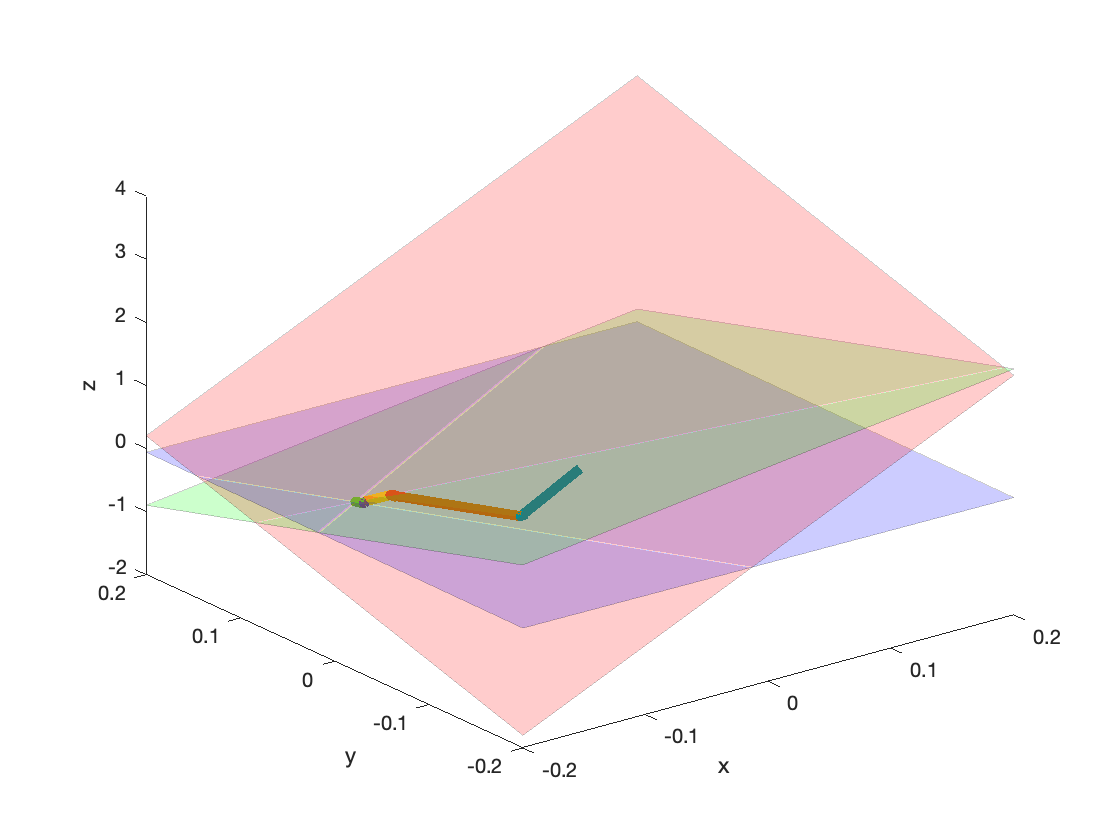

x=[-0.2,-0.2,0.2,0.2];
y=[0.2,-0.2,-0.2,0.2];
z1 = (b(1,1) - A(1,1).*x - A(1,2).*y)./A(1,3);
z2 = (b(2,1) - A(2,1).*x - A(2,2).*y)./A(2,3);
z3 = (b(3,1) - A(3,1).*x - A(3,2).*y)./A(3,3);

figure
hold on
% plot first plane:
p1=patch(x(:),y(:),z1(:),'red');
set(p1,'facealpha',0.2); set(p1,'edgealpha',0.2)
view(3);
xlabel('x')
ylabel('y')
zlabel('z')

% plot second plane:
p2=patch(x(:),y(:),z2(:),'green');
set(p2,'facealpha',0.2); set(p2,'edgealpha',0.2)

% plot third plane:
p3=patch(x(:),y(:),z3(:),'blue');
set(p3,'facealpha',0.2); set(p3,'edgealpha',0.2)

x_ktemp = [0;0;0];
for s = 1:1:2 % 2 sets
    for i = 1:1:length(b)
        jump=( 1.*norm(A(i,:)).^-2.*(( b(i,1)-(A(i,:)*x_ktemp) ).*A(i,:)'));
        quiver3(x_ktemp(1,1),x_ktemp(2,1),x_ktemp(3,1), jump(1,1),jump(2,1),jump(3,1), 1, 'linewidth',5)
        x_ktemp=x_ktemp + jump;
    end
end
hold off

## 5

5a)

i =[30 43 25 13 81 62];
j =[27 84 142 54 9 108];
aij =[0.6 0.9 -0.5 2.8 1.8 -1.8];

A = sparse(i,j,aij,100,200);

disp(['# of nonzero elements: ' num2str(nnz(A))])

# of nonzero elements: 6


5b)

% Matlab
% generate random 2150x2150 matrix A (seeded by 2023)
N=2150; rng(2023); A=rand(N,N);
% make a symmetric matrix across diagonal
% since vals are 0-1, <0.97 leaves only 3% nonzero elements, making a sparse matrix
A=(A'+A)/2; A(abs(A)<0.97)=0;
% shift the mean of nonzero elements to 0; increase range by 1000x
A(A~=0)=(A(A~=0)-mean(A(A~=0)))*1000;
% store A as a sparse matrix and show the count of non-zero elements
Asp=sparse(A); nnz(Asp)

ans = 8596

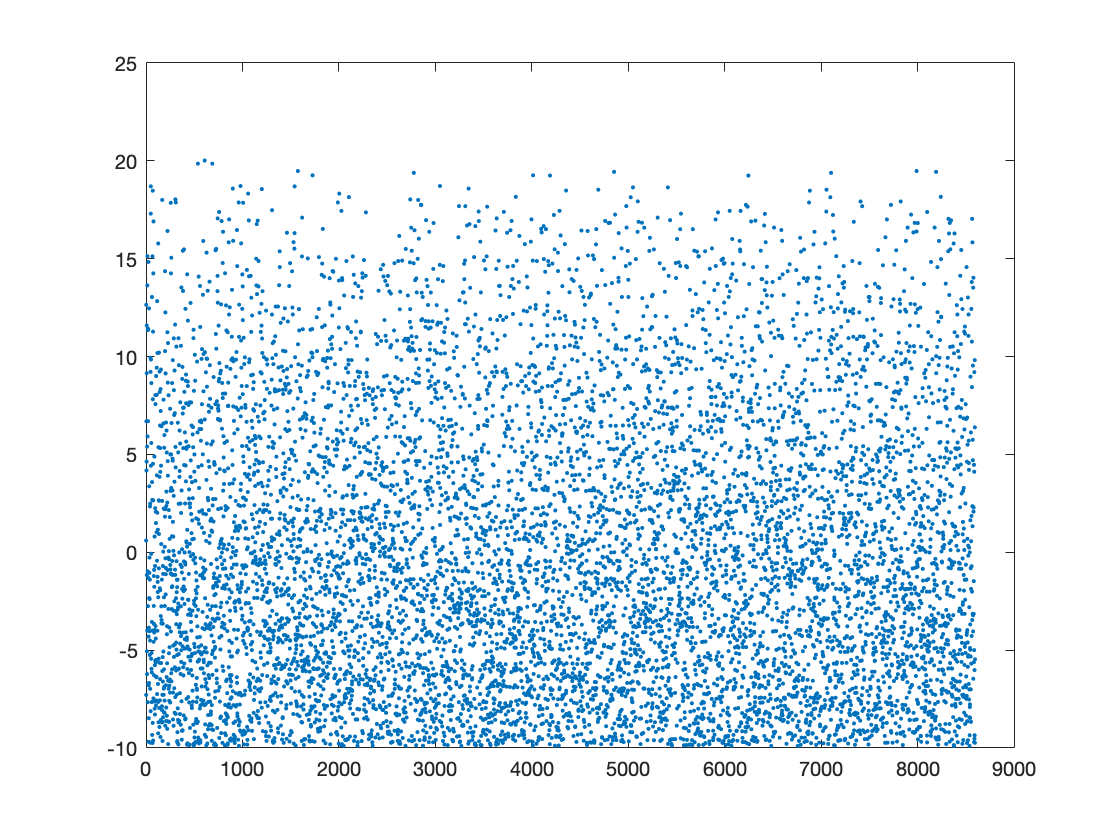

% select figure 1 and delete all visible children of this figure
figure(1); clf;
% visualize non-zero elements of A
plot(Asp(Asp~=0),'.')

% do a big computation with matrix not specially stored as sparse matrix
% (x5 by itself and add itself) and time this line
tic; X=A*A*A*A*A+A; toc;

Elapsed time is 1.231091 seconds.


% do a big computation with matrix stored as sparse matrix
% and time this line
tic; Xsp=Asp*Asp*Asp*Asp*Asp+Asp; toc;

Elapsed time is 0.074118 seconds.


So doing the computation with the matrix stored as a sparse matrix in Matlab is much faster when timed, so we should store matrices as sparse matrices if they are sparse.

## 6

6a)

A=[ 4.51383, 4.81534, 1.60189;...
2.57472, 3.69404, 1.5812;...
5.28217, -0.091319, -0.476303];

delta_b=[ -0.122189;...
0.155624;...
0.0291701];

b=[ -6.70581;...
-4.52604;...
-3.94298];

without_noise = inv(A)*b
with_noise = inv(A)*(b+delta_b)

without_noise =    -0.7747
   -0.6006
   -0.1978


with_noise =    -0.6940
   -1.0047
    0.7134


6b) Two of the planes are very close together and almost linearly dependent/on top of each other. Therefore, a small change in one of the planes could drastically change the location of the intersection.

6c)

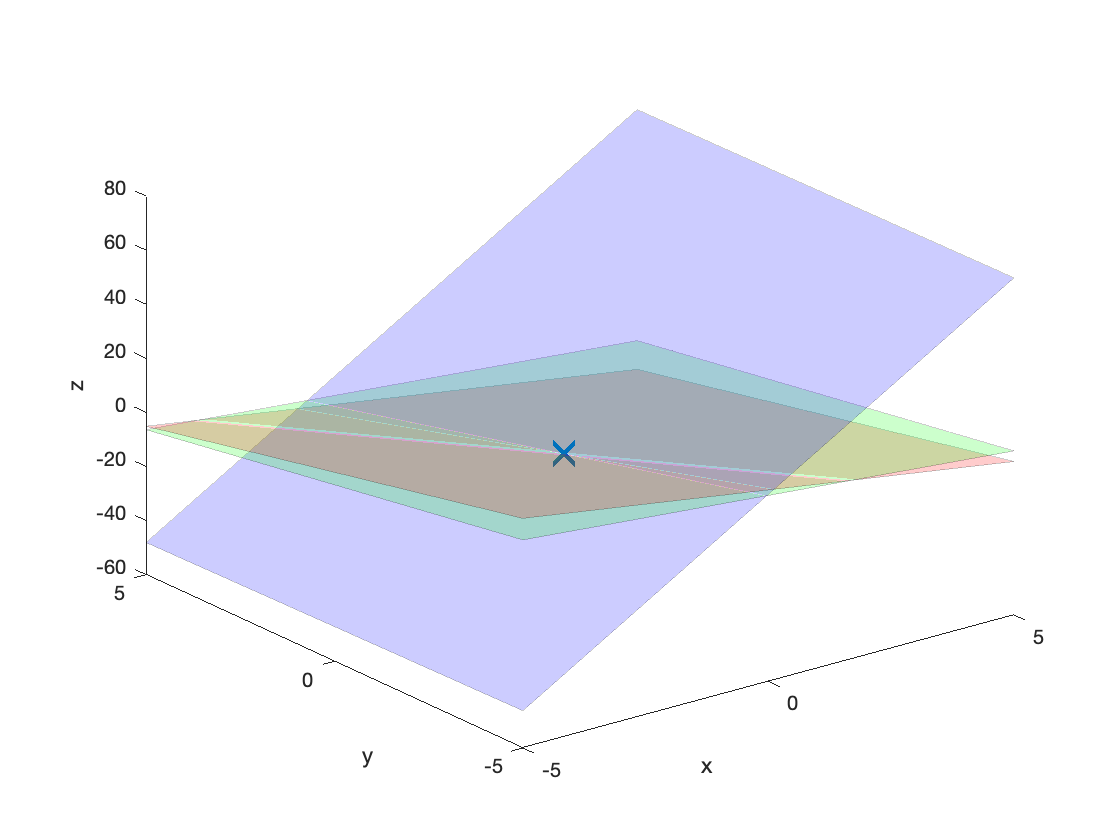

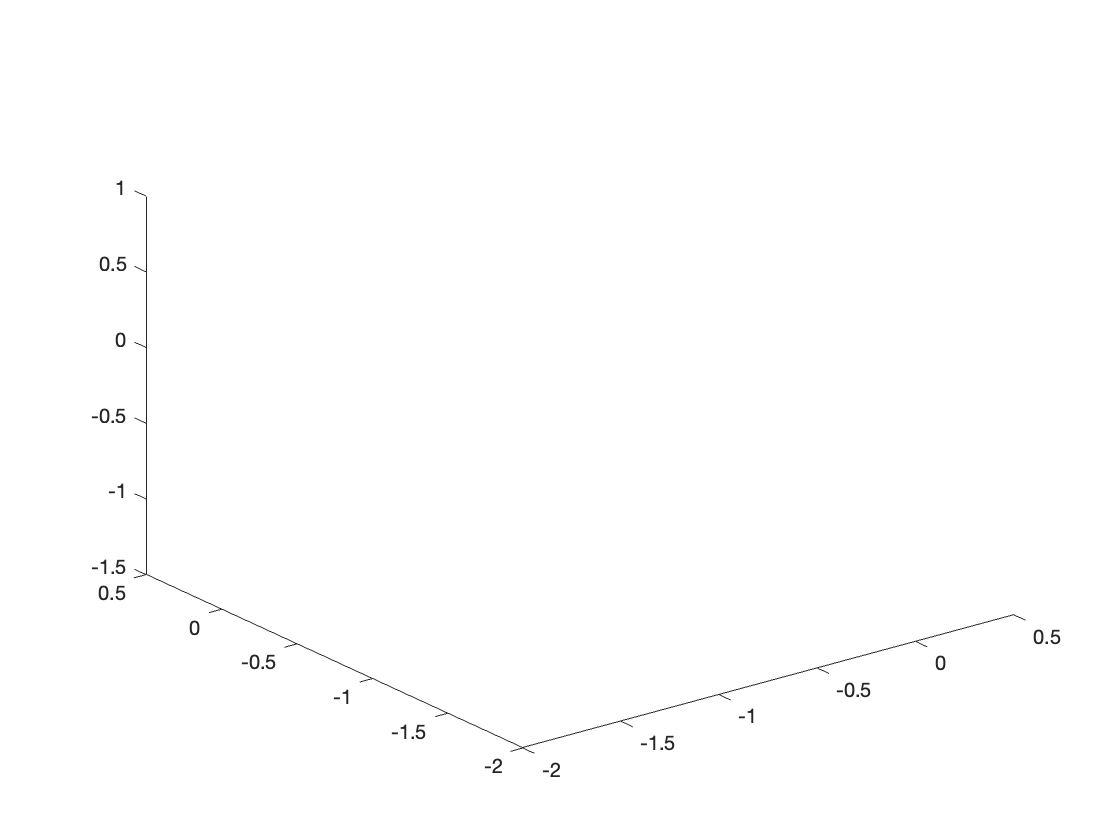

x=[-5,-5,5,5];
y=[5,-5,-5,5];
z1 = (b(1,1) - A(1,1).*x - A(1,2).*y)./A(1,3);
z2 = (b(2,1) - A(2,1).*x - A(2,2).*y)./A(2,3);
z3 = (b(3,1) - A(3,1).*x - A(3,2).*y)./A(3,3);

figure
hold on
% plot first plane:
p1=patch(x(:),y(:),z1(:),'red');
set(p1,'facealpha',0.2); set(p1,'edgealpha',0.2)
view(3);
xlabel('x')
ylabel('y')
zlabel('z')

% plot second plane:
p2=patch(x(:),y(:),z2(:),'green');
set(p2,'facealpha',0.2); set(p2,'edgealpha',0.2)

% plot third plane:
p3=patch(x(:),y(:),z3(:),'blue');
set(p3,'facealpha',0.2); set(p3,'edgealpha',0.2)

% plot location of solution:
plot3(without_noise(1,1),without_noise(2,1),without_noise(3,1),'x','markersize',14,'linewidth',3)

hold off

## 7

[7 png]

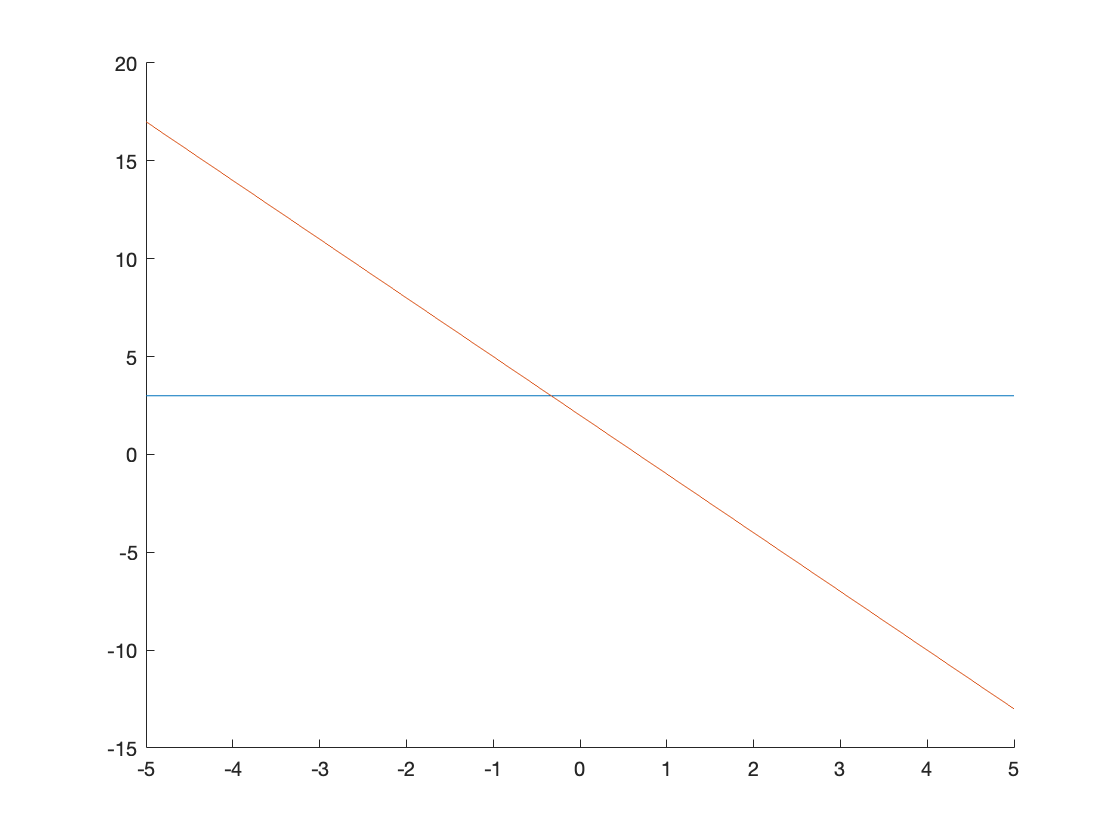

A=[0.0003 1;...
    3 1];
b=[3; 2];

% plotting the two line equations
figure
hold on
x = -5:1:5;
y1 = ( b(1,1)-(A(1,1).*x) ) ./A(1,2);
y2 = ( b(2,1)-(A(2,1).*x) ) ./A(2,2);
plot(x,y1)
plot(x,y2)
hold off

7 continued) No the matrix is not near-singular and the lines are not that close together. The source of sensitivity to noise is that we didn't pivot and with our 3-digit accuracy this led us to get a less accurate answer. If we had pivoted, even with the 3-digit accuracy, we would have gotten a closer answer.

## 8

8a) From a database with a list of all the friends for each user,

In the MAP stage: each user's line of friends is an individual chunk. From each chunk, [key, value] pairs are mapped where each key is a possible pair of friends from the friends list and the value is that particular user. This is done for all chunks/users.

In the SHUFFLE stage: All [key, value] pairs are shuffled and sorted (so all pairs with key=[user_A, user_B] are treated the same as pairs with key=[user_B, user_A]). All occurrences for each key/user pair are then returned.

In the REDUCE stage: All occurrences for each key/user pair are combined into a single list of mutual friends for that user pair.

8b) edits start @ line 238

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% find mutual facebook friends using MapReduce algorithm.

%% see
%% help/matlab/import_export/getting-started-with-mapreduce.html#bug4okz
%% Eli, APM120, 201906

%% select data file:
ds = datastore('Data/friends.txt');
% send a single line of the data to the map function each time:
ds.ReadSize=1;

%% display information about entire dataset:
ds

ds =   TabularTextDatastore with properties:

                      Files: {
                             '/Users/paulazhu/coding/class-notes/HW_01/Data/friends.txt'
                             }
               FileEncoding: 'UTF-8'
   AlternateFileSystemRoots: {}
          ReadVariableNames: false
              VariableNames: {'Var1', 'Var2', 'Var3' ... and 1 more}
             DatetimeLocale: en_US

  Text Format Properties:
             NumHeaderLines: 0
                  Delimiter: ' '
               RowDelimiter: '\r\n'
             TreatAsMissing: ''
               MissingValue: NaN

  Advanced Text Format Properties:
            TextscanFormats: {'%f', '%f', '%f' ... and 1 more}
                   TextType: 'char'
         ExponentCharacters: 'eEdD'
               CommentStyle: ''
                 Whitespace: '\b\t'
    MultipleDelimitersAsOne: false

  Properties that control the t

fprintf(1,'specified dataset ReadSize=%d\n',ds.ReadSize);

specified dataset ReadSize=1


%% show a few data values:
fprintf(1,'\n\nA preview of some of the flight data values:\n')



A preview of some of the flight data values:


preview(ds)

ans = 5×4 table
    Var1    Var2    Var3    Var4
    ____    ____    ____    ____

     1       2       3        4 
     2       1       3        5 
     3       1       2        5 
     4       1       5      NaN 
     5       2       3        4 


%% calculate mean daily flight delay using MapReduce:
outds = mapreduce(ds, @mutual_friends_MapFun, @mutual_friends_ReduceFun ...
                  ,'OutputFolder','./Output/friends/');

Parallel mapreduce execution on the parallel pool:
********************************
*      MAPREDUCE PROGRESS      *
********************************
Map   0% Reduce   0%
--> entering map function: size(data)=1x4
info.Offset=0, info.NumCharactersRead=8
exiting map function Mean_Daily_Delay_MapFun
--> entering map function: size(data)=1x4
info.Offset=8, info.NumCharactersRead=8
exiting map function Mean_Daily_Delay_MapFun
--> entering map function: size(data)=1x4
info.Offset=16, info.NumCharactersRead=8
exiting map function Mean_Daily_Delay_MapFun
--> entering map function: size(data)=1x4
info.Offset=24, info.NumCharactersRead=7
exiting map function Mean_Daily_Delay_MapFun
--> entering map function: size(data)=1x4
info.Offset=31, info.NumCharactersRead=7
exiting map function Mean_Daily_Delay_MapFun

Map  50% Reduce   0%
Map 100% Reduce   0%
--> entering reduce function, intermKey = 2 4:
 key=2 4; mutual_friends:  1, 5, 
exiting reduce function Mean_Daily_Delay_ReduceFun.

--> entering r


%% read and display results:
a=readall(outds);
N=length(a.Key);
disp('users: mutual friends')

users: mutual friends


for i=1:N
  fprintf(1,'%s:   ',char(a.Key(i)));
  fprintf('%d,',cell2mat(a.Value(i)));
  fprintf('\n');
end

2 4:   

1,5,

1 2:   

3,

2 5:   

3,

3 4:   

1,5,

3 5:   

2,

1 3:   

2,

1 5:   

2,3,4,

2 3:   

1,5,


%% now display number of mutual friends for each user pair
disp('now display number of mutual friends for each user pair')

now display number of mutual friends for each user pair


disp('users: # of mutual friends')

users: # of mutual friends


for i=1:N
  fprintf(1,'%s:   ',char(a.Key(i)));
  fprintf('# of mutual friends = %d,',length(cell2mat(a.Value(i))));
  fprintf('\n');
end

2 4:   

# of mutual friends = 2,

1 2:   

# of mutual friends = 1,

2 5:   

# of mutual friends = 1,

3 4:   

# of mutual friends = 2,

3 5:   

# of mutual friends = 1,

1 3:   

# of mutual friends = 1,

1 5:   

# of mutual friends = 3,

2 3:   

# of mutual friends = 2,



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function mutual_friends_MapFun(data, info, intermKVStore)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Map function: input is a chunk of the data. Output is the sum
%% over delays and number of delay events per each day, for this
%% chunk only, returned as a (KEY,VALUE) pair. 

fprintf(1,['--> entering map function: ' ...
           'size(data)=%dx%d\n'] ,size(data));
fprintf(1,'info.Offset=%d, info.NumCharactersRead=%d\n' ...
        ,info.Offset,info.NumCharactersRead);

%% Initialize variables 
%% calculate sum over delays and number of delay events, per each
%% day, only for the current chunk of data:
input_data=table2array(data);
user=input_data(1);
friends=input_data(2:end);
Nfriends=length(friends);
for i=1:Nfriends
  for j=1:Nfriends
    friend1=friends(i);
    friend2=friends(j);
    if friend1>friend2
      %% returned KEY is pair of friends;
      %% returned VALUE is the user on this line
      %% add(intermKVStore, KEY, VALUE)
      key=sort([friend1,friend2]);
      key_character=sprintf('%d %d',key);
      add(intermKVStore, key_character, user);
    end
  end
end
fprintf(1,'exiting map function Mean_Daily_Delay_MapFun\n');
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function mutual_friends_ReduceFun(intermKey, intermValIter, outKVStore)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Reduce function. Called once for each value of the key.  We
%% have 7 values corresponding to 7 days. Each call to this reduce
%% function therefore deals with flight delay data corresponding to
%% one day.

fprintf(1,'--> entering reduce function, intermKey = %s:\n',intermKey);

%% Loop over all data belonging to the day given by intermKey:
%% This is based on the SHUFFLE STEP, because mapreduce now needs to
%% sort all keys and return here only the ones we are requesting:
num_mutual_friends=0;
while hasnext(intermValIter)
  num_mutual_friends=num_mutual_friends+1;
  next_value=getnext(intermValIter);
  %% calculate the sum over delays and the number of delays:
  mutual_friends(num_mutual_friends) = next_value;
end
%% return output of calculation for each day, again as a (KEY,VALUE)
%% pair, where the key is the day and the value is the mean delay:
add(outKVStore, intermKey, mutual_friends);

fprintf(1,' key=%s; mutual_friends: ',intermKey)
fprintf(1,' %d,',mutual_friends)
fprintf(1,' \n')
fprintf(1,'exiting reduce function Mean_Daily_Delay_ReduceFun.\n');
end